## Plot assimilation rates for rice data 

#### These could also be compared against potato data

Import assimilation rates from results file:

file = 'Results_optimization_rice.xlsx';
optimized_averages = 'G4'; % average assimilation rate from each sheet
optimized_reps_range = 'I4:R4'; % if we want to use all 10 reps instead of only the averages 

Get the assimilation results from three enzymes with optimized amounts.

Define sheet names to import data from:

sheet_names = string(num2cell(140:20:420));

Import non assimilation rates from text file (generated after running CalculateGrossAssimilation):

non_optimized_data = num2cell(readmatrix('non_optimized_A.txt'));
% optimized_280_A = num2cell(readmatrix('optimized_280_A.txt'));
% optimized_420_A = num2cell(readmatrix('optimized_420_A.txt'));

reoptimized_140_A = num2cell(readmatrix('reoptimized_140_A.txt'));
reoptimized_280_A = num2cell(readmatrix('reoptimized_280_A.txt'));
reoptimized_420_A = num2cell(readmatrix('reoptimized_420_A.txt'));

Create cell array to import average assimilation rates from each Ci/sheet:

%assimilation_data = cell(4, numel(sheet_names));
reoptimized_assimilation_data = cell(5, numel(sheet_names));

Convert sheet_names into x values: 

Ci = str2double(sheet_names);

Loop through all sheets and import values into assimilation_data:

for i = 1:numel(Ci)
    % Read the specified range as a numeric array
    % assimilation_data{1,i} = non_optimized_data{i,1};
    % assimilation_data{2,i} = xlsread(file, char(sheet_names(i)), optimized_averages);
    % assimilation_data{3,i} = optimized_280_A{i,1};
    % assimilation_data{4,i} = optimized_420_A{i,1};
    reoptimized_assimilation_data{1,i} = non_optimized_data{i,1};
    reoptimized_assimilation_data{2,i} = xlsread(file, char(sheet_names(i)), optimized_averages);
    reoptimized_assimilation_data{3,i} = reoptimized_140_A{i,1};
    reoptimized_assimilation_data{4,i} = reoptimized_280_A{i,1};
    reoptimized_assimilation_data{5,i} = reoptimized_420_A{i,1};
end

Plot assimilation rates' averages against Ci:

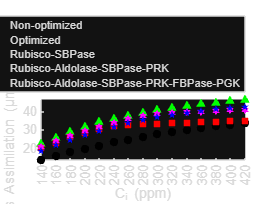

figure;
% Plot scatter graph of Ci (x) against average assimilation rates
% Plot non-optimized A
scatter(Ci, cell2mat(reoptimized_assimilation_data(1,:)),'black','filled','o'); 
hold on
% Plot optimized A averages
scatter(Ci, cell2mat(reoptimized_assimilation_data(2,:)),'green','filled','^');
hold on
% Plot non-optimized A with optimized A averages for Rubisco, SBPase at 140
scatter(Ci, cell2mat(reoptimized_assimilation_data(3,:)),'red','filled','square');
hold on
% Plot non-optimized A with optimized A averages for Rubisco, Aldolase, SBPase, PRK at 280
scatter(Ci, cell2mat(reoptimized_assimilation_data(4,:)),'magenta','filled','h');
hold on
% Plot non-optimized A with optimized A averages for Rubisco, Aldolase, SBPase, PRK, FBPase, PGK at 420
scatter(Ci, cell2mat(reoptimized_assimilation_data(5,:)),'blue','filled','p');
hold on
xlim([min(Ci), max(Ci)]); % Ci x axis limits
xticks(Ci)
xticklabels(Ci)
xlabel('C_i (ppm)','FontSize', 10);
ylabel('Gross Assimilation (μmol m^{-2} s^{-1})','FontSize', 10);
legend('Non-optimized','Optimized','Rubisco-SBPase','Rubisco-Aldolase-SBPase-PRK','Rubisco-Aldolase-SBPase-PRK-FBPase-PGK','Location', 'NorthOutside')
hold off
set(gcf, 'PaperOrientation', 'landscape');
print(gcf,fullfile('Outputs/rice_params/graphs',"Ci_vs_Assimilation"),'-dpdf','-bestfit');